# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

## 实验八 FIR数字滤波器

## 一、实验目的

- 掌握线性相位滤波器符幅特性和零极点分布的研究方法

- 用MATLAB研究线性相位滤波器特性时程序编写思路和方法

- 加深对窗函数法设计FIR数字滤波器的基本原理的理解

- 用MATLAB的窗函数法编写设计FIR数字滤波器的程序

- 加深对频率采样法设计FIR数字滤波器的基本原理的理解

- 掌握在频域优化设计FIR数字滤波器的方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

**1.窗函数法设计FIR滤波器**

        FIR滤波器的设计任务是选择有限长度的$h\left(n\right)$，使传输函数$H\left(e^{jw} \right)$满足技术要求。主要设计方法有窗函数法、频率采样法和切比雪夫等波纹逼近法等。本实验主要介绍用窗函数法设计 FIR 数字滤波器。

        用窗函数法设计 FIR数字滤波器的基本步骤是:

        (1)根据过渡带和阻带衰减设计指标选择窗函数的类型，估算滤波器的阶数N。

        (2)由数字滤波器的理想频率响应$H\left(e^{jw} \right)$求出其单位冲激响应$h_d \left(n\right)$。

        (3)计算数字滤波器的单位冲激响应$h\left(n\right)=w\left(n\right)h_d \left(n\right)$。

        (4)检查设计出的滤波器是否满足技术指标。

        如果不满足技术指标，则需要重新选择或调整窗函数的类型，估算滤波器的阶数N。再重复前面的四个步骤，直到满足指标为止。

常用的窗函数有矩形窗、三角形窗、汉宁窗、哈明窗、切比雪夫窗、布莱克曼窗、凯塞窗等，MATLAB均有相应的子函数可以调用。

**2.频率采样法设计FIR滤波器**

        设计滤波器时，通常给出的是幅频特性的技术指标要求，可直接在频域进行处理，按照理想的频率特性$H\left(e^{jw} \right)$，在$w=0$到$2\pi$之间等间隔采样N点，得到：


$$H{\left(k\right)}={{\left(H\left(e^{jw} \right)\right|}}_{w=2k\pi /N}$$


        然后用$H\left(k\right)$的傅里叶逆变换作为滤波器的系数：


$$b{\left(n\right)}=h{\left(n\right)}=IDFT\left\lbrack H\left(k\right)\right\rbrack$$


        构成一个系统传递函数为$H\left(z\right)=\sum_{n=0}^{N-1} h{\left(n\right)}*z^{-n}$的实际的FIR数字波器，这种设计方法称为频率采样法。其中$H\left(z\right)$与$H\left(k\right)$的关系符合内插公式，即


$$H{\left(z\right)}=\frac{1-z^{-N} }{N}\sum_{n=0}^{N-1} \frac{H\left(k\right)}{1-e^{\frac{j2\pi k}{N}} z^{-1} }$$


## 四、实验所用MATLAB函数

- blackman函数：产生n点的blackman窗。

- hamming函数：产生n点的hamming窗。

- hanning函数：产生n点的hanning窗。

- fir1函数：基于窗函数的FIR数字滤波器的设计，已经经典方法实现加窗线性相位的FIR滤波器设计，可以设计标准的低通、带通、高通和带阻滤波器。

- fir2函数：基于频率样本法的FIR数字滤波器的设计，用于任意频率响应的加窗数字FIR滤波器的设计。

## 五、实验内容、方法、代码与结果

### **题目1**：由序列$h0=[3,-1,2,-3]$为基础，构成四种类型的线性相位FIR滤波器，即

- $h1=[3,-1,2,-3,5,-3,2,-1,3]$;

- $h2=[3,-1,2,-3,-3,2,-1,3]$;

- $h3=[3,-1,2,-3,0,3,-2,1,-3]$;

- $h4=[3,-1,2,-3,3,-2,1,-3]$;

分别求它们的冲激响应和符幅特性，并在同一张图纸上描绘出来进行分析比较。

**解答1**：

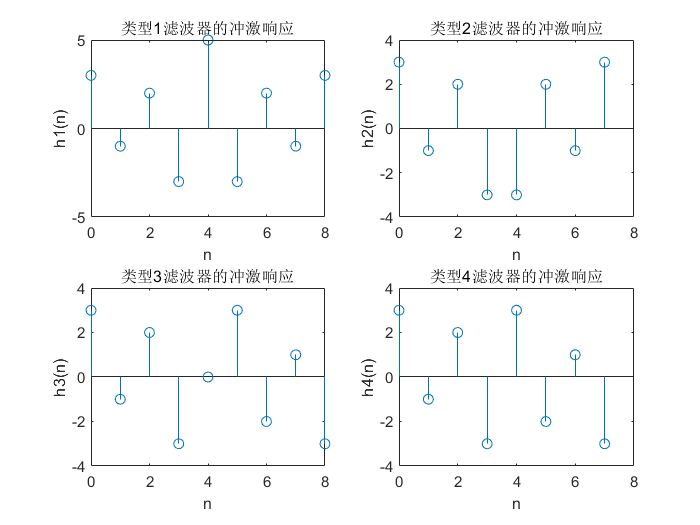

clc;
clear;
h1=[3,-1,2,-3,5,-3,2,-1,3];
h2=[3,-1,2,-3,-3,2,-1,3];
h3=[3,-1,2,-3,0,3,-2,1,-3];
h4=[3,-1,2,-3,3,-2,1,-3];
[A1,w1,type1,tao1]=amplres(h1);
[A2,w2,type2,tao2]=amplres(h2);
[A3,w3,type3,tao3]=amplres(h3);
[A4,w4,type4,tao4]=amplres(h4);
figure();
subplot(2,2,1);
stem(0:length(h1)-1,h1);
xlabel('n');
ylabel('h1(n)');
title('类型1滤波器的冲激响应');
subplot(2,2,2);
stem(0:length(h2)-1,h2);
xlabel('n');
ylabel('h2(n)');
title('类型2滤波器的冲激响应');
subplot(2,2,3);
stem(0:length(h3)-1,h3);
xlabel('n');
ylabel('h3(n)');
title('类型3滤波器的冲激响应');
subplot(2,2,4);
stem(0:length(h4)-1,h4);
xlabel('n');
ylabel('h4(n)');
title('类型4滤波器的冲激响应');

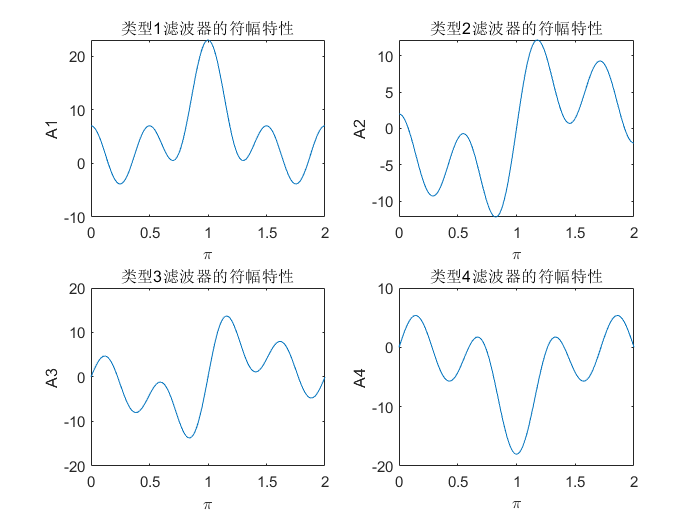


figure();
subplot(2,2,1);
plot(w1/pi,A1);
xlabel('\pi');
ylabel('A1');
title('类型1滤波器的符幅特性');
subplot(2,2,2);
plot(w2/pi,A2);
xlabel('\pi');
ylabel('A2');
title('类型2滤波器的符幅特性');
subplot(2,2,3);
plot(w3/pi,A3);
xlabel('\pi');
ylabel('A3');
title('类型3滤波器的符幅特性');
subplot(2,2,4);
plot(w4/pi,A4);
xlabel('\pi');
ylabel('A4');
title('类型4滤波器的符幅特性');

### **题目2**：求解线性相位系统$h=[3,-1,2,-3,6,-3,2,-1,3]$的零极点分布图，并观察实数零点和复数零点成组出现的特点。

**解答2**：

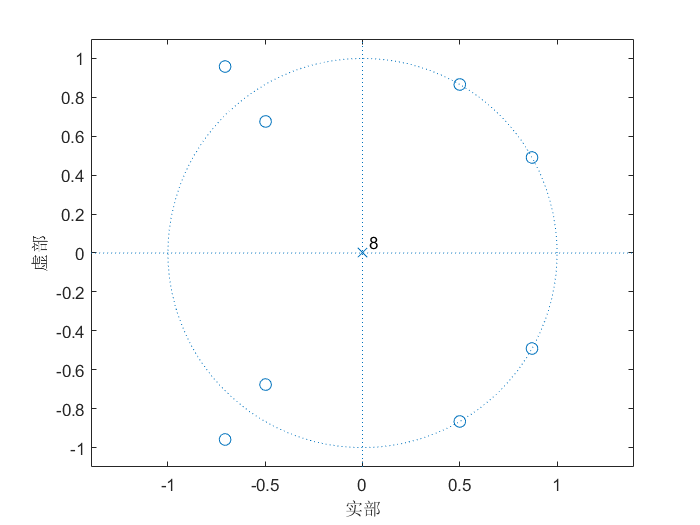

clc;
clear;
figure();
h=[3,-1,2,-3,6,-3,2,-1,3];
zplane(h,1);

disp(['线性相位FIR滤波器的零点分为三种情况，本题占了其中的两种：' ...
    '1、实数零点或单位圆上的复数零点按z和1/z成对出现；' ...
    '2、非单位圆上的复数零点，则按z,z*,1/z,(1/z)*四个点同时出现。'])

线性相位FIR滤波器的零点分为三种情况，本题占了其中的两种：1、实数零点或单位圆上的复数零点按z和1/z成对出现；2、非单位圆上的复数零点，则按z,z*,1/z,(1/z)*四个点同时出现。


### **题目3**：选择合适的窗函数设计FIR数字低通滤波器，要求通带$\omega_{p}=0.2\pi,R_{p}=0.05dB$；阻带$\omega_s=0.3\pi,A_s=40dB$。描绘实际滤波器的脉冲响应、窗函数及滤波器的幅频响应曲线和相频响应曲线。

**解答3**：

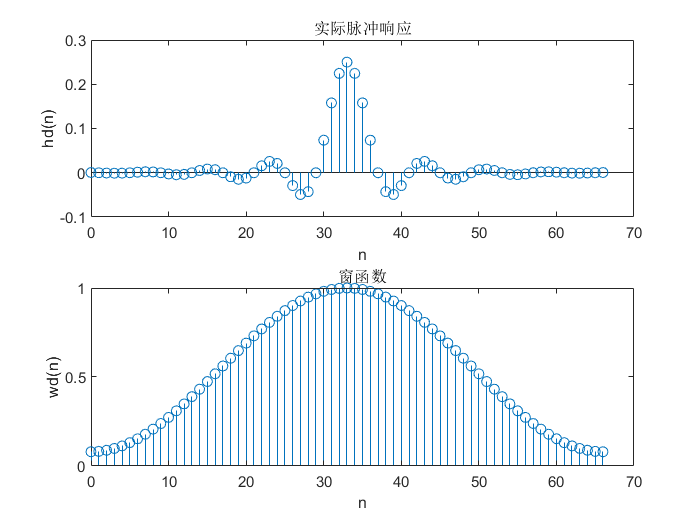

clc;
clear;
wp=0.2*pi;
Rp=0.05;
ws=0.3*pi;
As=40;%设计指标
Bt=ws-wp;%过渡带宽度
N0=ceil(6.6*pi/Bt);%滤波器长度
N=N0+mod(N0+1,2);%应确保N为奇数
n=0:N-1;
win=(hamming(N))';%使用Hamming窗并变为行向量
wc=(ws+wp)/2;
hd=ideal_lp(wc,N);
b=hd.*win;%求FIR系统函数系数
[db,mag,pha,grd,w]=freqz_m(b,1);
figure();
subplot(2,1,1);
stem(n,b);
title('实际脉冲响应');
xlabel('n');
ylabel('hd(n)');
subplot(2,1,2);
stem(n,win);
title('窗函数');
xlabel('n');
ylabel('wd(n)');

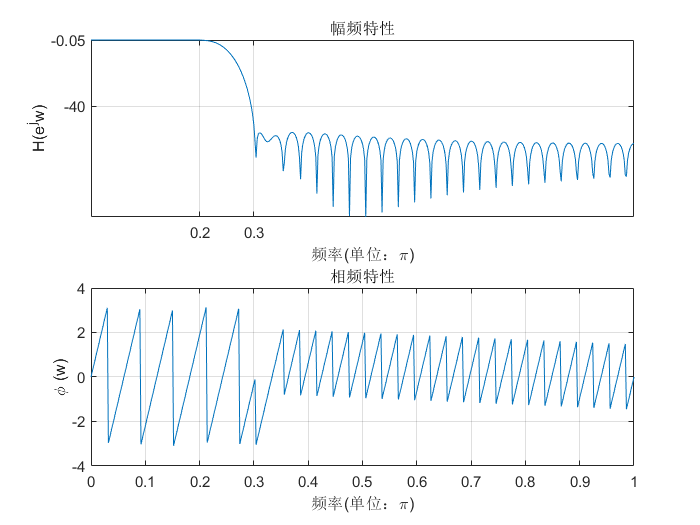

figure();
subplot(2,1,1);
plot(w/pi,db);
title('幅频特性');
set(gca,'Xtick',[wp/pi,ws/pi]);
set(gca,'Ytick',[-As,-Rp]);
grid
xlabel('频率(单位：\pi)');
ylabel('H(e^jw)');
subplot(2,1,2);
plot(w/pi,pha);
title('相频特性');
grid on
xlabel('频率(单位：\pi)');
ylabel('{\phi (w)}');

### **题目4**：选择合适的窗函数设计FIR数字带阻滤波器，要求：$f_{p1}=1kHz,f_{p2}=4.5kHz,R_p=0.1dB$；$f_{s1}=2kHz,f_{s2}=3.5kHz,A_s=40dB$，滤波器采样频率$F_s=10kHz$。描绘实际滤波器的脉冲响应、窗函数及滤波器的幅频响应曲线和相频响应曲线。

**解答4**：

clc;
clear;
Fs=10e3;
ws1=2e3/(Fs/2)*pi;
ws2=3.5e3/(Fs/2)*pi;
ws=[ws1,ws2];
wp1=1e3/(Fs/2)*pi;
wp2=4.5e3/(Fs/2)*pi;
wp=[wp1,wp2];
Rp=0.1;
As=40;
Bw=ws1-wp1;
N=ceil(6.2*pi/Bw);
N=N+mod(N+1,2);%应确保N为奇数
win=(hanning(N))';%使用hanning窗
wc1=(ws1+wp1)/2;
wc2=(ws2+wp2)/2;%截止频率取阻带频率的平均值
hd=ideal_lp(wc1,N)+ideal_lp(pi,N)-ideal_lp(wc2,N);
b=hd.*win;%求FIR系统函数系数
[db,mag,pha,grd,w]=freqz_m(b,1);
n=0:N-1;dw=2*pi/1000;
wp0=[1:wp1/dw+1,wp2/dw+1:501];
Rp=-(min(db(wp0)))

Rp = 0.0938

As=-round(max(db(ws1/dw+1:ws2/dw+1)))%检验最小阻带衰减

As = 44

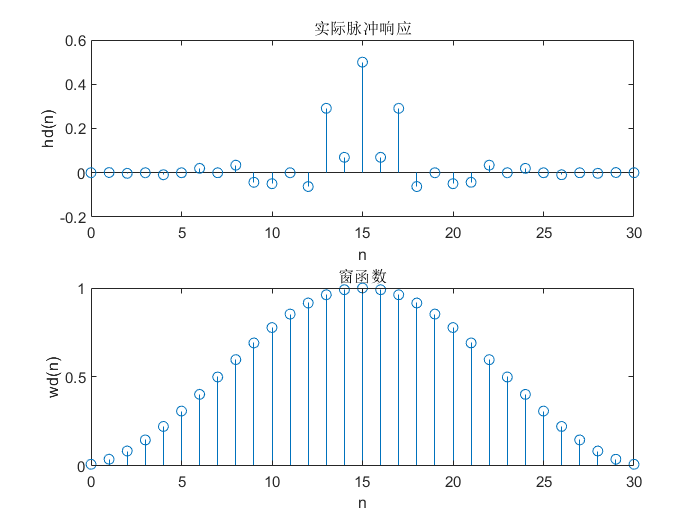


figure();
subplot(2,1,1);
stem(n,b);
title('实际脉冲响应');
xlabel('n');
ylabel('hd(n)');
subplot(2,1,2);
stem(n,win);
title('窗函数');
xlabel('n');
ylabel('wd(n)');

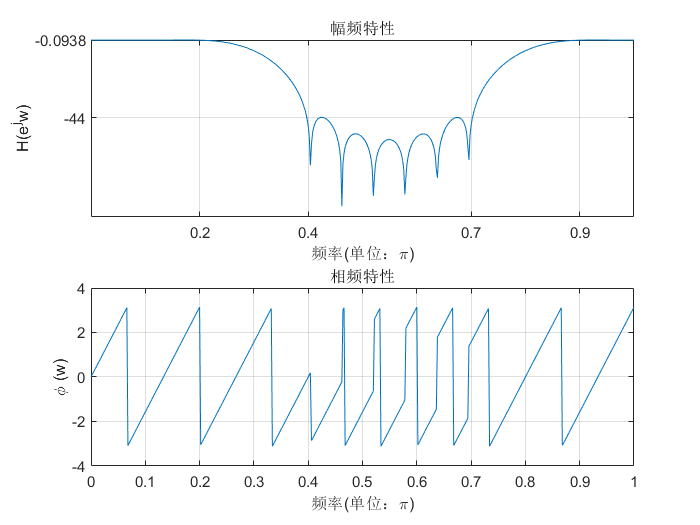

figure();
subplot(2,1,1);
plot(w/pi,db);
title('幅频特性');
set(gca,'Xtick',[wp1/pi,ws1/pi,ws2/pi,wp2/pi]);
set(gca,'Ytick',[-As,-Rp]);
grid
xlabel('频率(单位：\pi)');
ylabel('H(e^jw)');
subplot(2,1,2);
plot(w/pi,pha);
title('相频特性');
grid on
xlabel('频率(单位：\pi)');
ylabel('{\phi (w)}');

### **题目5**：试用两种方法设计FIR数字带通滤波器，要求：$\omega_{p1}=0.4\pi，\omega_{p2}=0.6\pi$；$\omega_{s1}=0.25\pi，\omega_{s2}=0.75\pi$，取N=41，描绘滤波器的脉冲响应、幅频响应和相频响应曲线，并观察通阻带衰减指标。

- 用频率采样优化设计法设计，在过渡带增加一点采样点，取$T_1=0.38$

- 用fir2子函数设计，加`Blackman`窗，在过渡带增加一点采样点，取$T_1=0.38$

**解答5**：

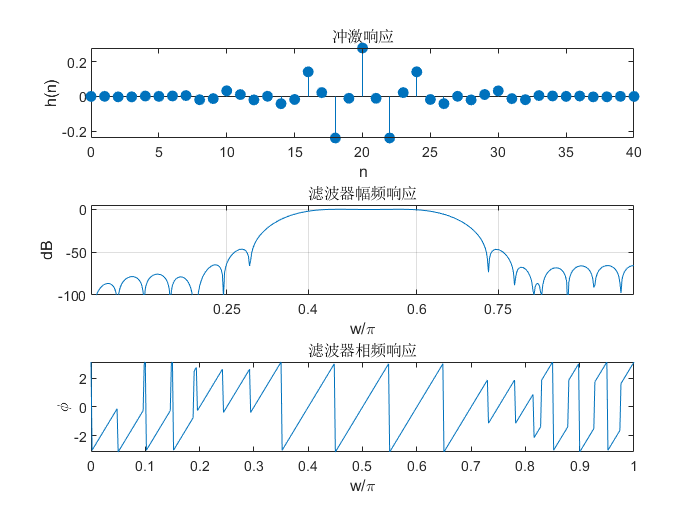

clc;
clear;
%方法1
wp1=0.4*pi;
wp2=0.6*pi;
ws1=0.25*pi;
ws2=0.75*pi;
N=41;
T1=0.38;
n=0:N-1;
bw=wp2-wp1;
N1=round(bw/(2*pi)*N);
N1=N1+mod(N1+1,2);
N2=round((N-2*N1-5)/4);
N2=N2+mod(N2+1,2);
N3=N-2*N1-2*N2-4;
A=[zeros(1,N2),T1,ones(1,N1),T1,zeros(1,N3),T1,ones(1,N1),T1,zeros(1,N2)];
theta=-pi*(N-1)/N*n;
Hk=A.*exp(j*theta);
h=real(ifft(Hk));
[db,mag,pha,grd,w]=freqz_m(h,1);
figure()
subplot(3,1,1)
stem(n,h,"filled");
title('冲激响应')
xlabel('n');
ylabel('h(n)');
subplot(3,1,2)
plot(w/pi,db);
title('滤波器幅频响应');
xlabel('w/\pi');
ylabel('dB');
set(gca,'Xtick',[0.25,0.4,0.6,0.75]);
grid
axis([0 1 -100 5]);
subplot(3,1,3)
plot(w/pi,pha);

title('滤波器相频响应');

观察可得Rp=2.2dB,As=47dB


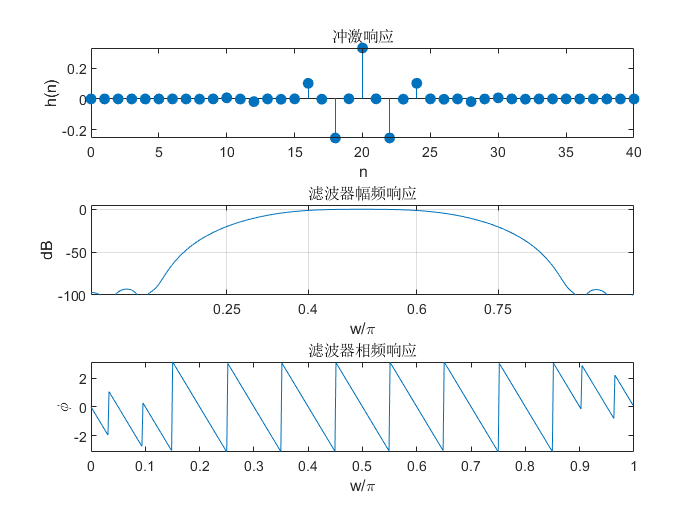

xlabel('w/\pi');
ylabel('\phi');
disp('通过观察图像可得Rp=2.2dB,As=47dB');
%方法2
wc1=(ws1+wp1)/2;wc2=(ws2+wp2)/2;
f=[0,ws1/pi,wc1/pi,wp1/pi,wp2/pi,wc2/pi,ws2/pi,1];
m=[0,0,T1,1,1,T1,0,0];
windows=blackman(N);
b=fir2(N-1,f,m,windows);
[H,w]=freqz(b,1);
dbH=20*log10((abs(H)+eps)/max(abs(H)));
figure()
subplot(3,1,1)
stem(n,b,"filled");
title('冲激响应')
xlabel('n');
ylabel('h(n)');
subplot(3,1,2)
plot(w/pi,dbH);
title('滤波器幅频响应');
xlabel('w/\pi');
ylabel('dB');
set(gca,'Xtick',[0.25,0.4,0.6,0.75]);
grid
axis([0 1 -100 5]);
subplot(3,1,3)
plot(w/pi,angle(H));

title('滤波器相频响应');

观察可得Rp=1.5dB,As=20dB


xlabel('w/\pi');
ylabel('\phi')
disp('通过观察图像可得Rp=1.5dB,As=20dB');

function[A,w,type,tao] = amplres(h)
% 给定FIR滤波器系数,求滤波器符幅特性
% h＝FIR滤波器的脉冲响应或分子系数向量
% A＝滤波器的符幅特性
% w＝频率向量,在0到pi之间分成500份,501个点
% type＝线性相位滤波器的类型
% tao＝符幅特性的群时延
N = length(h);tao = (N-1)/2;
L = floor((N-1)/2); % 求滤波器的阶次及符幅特性的阶次
n = 1:L+1;
w = [0:500]*2*pi/500; % 取滤波器频率向量
if all(abs(h(n)-h(N-n+1))<1e-10)   % 判断滤波器系数,若为对称
A = 2*h(n)*cos(((N+1)/2-n)'*w)-mod(N,2)*h(L+1);
% 对称条件下计算A(两种类型)
% 在N＝奇数时,h(L+1)多算一倍,要减掉。N为偶数时,
% 乘以mod(N,2)以取消这项
type = 2-mod(N,2);     % 判断并给出类型
elseif all(abs(h(n)+h(N-n+1))<1e-10)&(h(L+1)*mod(N,2)==0) % 系数若为反对称
% 在N＝奇数时,h(L+1)为零是奇对称判别条件之一,
% N为偶数时,乘以mod(N,2)以取消这项
A = 2*h(n)*sin(((N+1)/2-n)'*w); % 反对称条件下计算A(两种类型)
type = 4-mod(N,2); % 判断并给出类型
else error('错误：这不是线性相位滤波器!') % 滤波器系数非对称,报告错误
end
end

function hd = ideal_lp(wc,N)
% hd = 点0到N-1之间的理想脉冲响应
% wc = 截止频率(弧度)
% N = 理想滤波器的长度
tao = (N-1)/2;
n = [0:(N-1)];
m = n-tao+eps;  % 加一个小数以避免0作除数
hd = sin(wc*m)./(pi*m);
end
% 计算滤波器的绝对和相对幅度频率响应和相位频率响应

function [db,mag,pha,grd,w] = freqz_m(b,a)
[H,w] = freqz(b,a,1000,'whole');
H = (H(1:501))';w = (w(1:501))';
mag = abs(H);
db = 20*log10((mag+eps)/max(mag));
pha = angle(H);
grd = grpdelay(b,a,w);
end